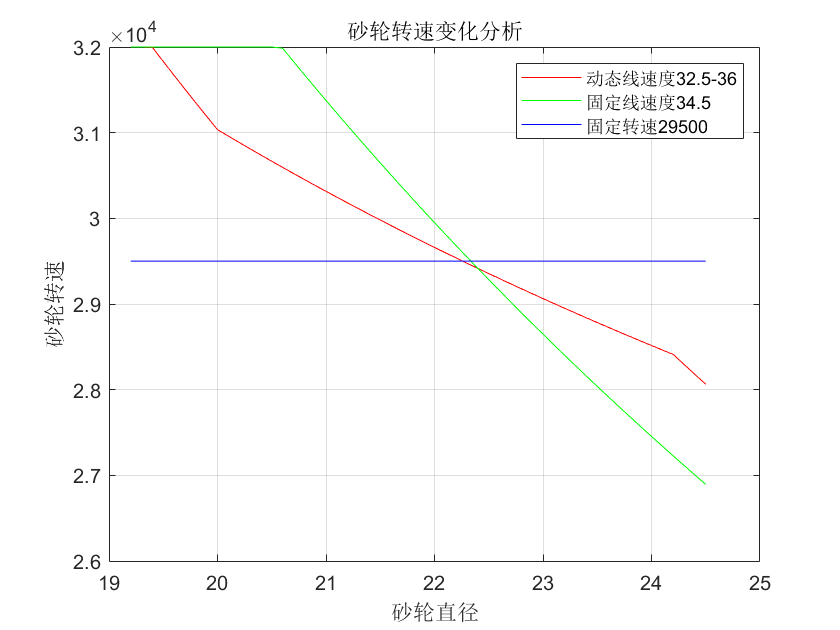

%*********************
%参数设置
wheelDiaMaxReal = 24.5;%砂轮最大直径
wheelDiaMinReal = 19.2;%砂轮最小直径

wheelDiaMax = 24.2;%最高线速度对应砂轮直径
wheelDiaMin = 20.0;%最低线速度对应砂轮直径
lineSpeedMax = 36;%最高线速度
lineSpeedMin = 32.5;%最低线速度

rpmMax = 32000;%最大砂轮转速限制
linSpeedPersist = 34.5;%恒线速度设置
rpmPersistSet = 29500;%恒转速设置

%*********************
%动态线速度转速计算
wheelDiaCurrent = wheelDiaMaxReal:-0.1:wheelDiaMinReal;
count = length(wheelDiaCurrent(:));

wheelDiaPercent = zeros(1, count);
lineSpeedCurrent = zeros(1, count);
rpmCurrent = zeros(1, count);

for k = 1:count
    wheelDiaPercent(k) = (wheelDiaCurrent(k) - wheelDiaMin) / (wheelDiaMax - wheelDiaMin);
    if wheelDiaPercent(k) > 1
        lineSpeedCurrent(k) = lineSpeedMax;
    elseif wheelDiaPercent(k) < 0
        lineSpeedCurrent(k) = lineSpeedMin;
    else
        lineSpeedCurrent(k) = (lineSpeedMax - lineSpeedMin) * wheelDiaPercent(k) + lineSpeedMin;
    end
    
    rpmCurrent(k) = lineSpeedCurrent(k) * 1000 * 60 / pi / wheelDiaCurrent(k);
    if rpmCurrent(k) > rpmMax
        rpmCurrent(k) = rpmMax;
    end
end

%*********************
%恒线速度转速计算
rpmPersistlinespeed = zeros(1, count);
for k = 1:count
    rpmPersistlinespeed(k) = linSpeedPersist * 1000 * 60 / pi / wheelDiaCurrent(k);
    if rpmPersistlinespeed(k) > rpmMax
        rpmPersistlinespeed(k) = rpmMax;
    end
end

%*********************
%恒转速计算
rpmPersist = zeros(1, count);
for k = 1:count
    rpmPersist(k) = rpmPersistSet;
end

%*********************
%绘图
plot(wheelDiaCurrent, rpmCurrent, 'r-')
hold on;
plot(wheelDiaCurrent, rpmPersistlinespeed, 'g-')
hold on;
plot(wheelDiaCurrent, rpmPersist, 'b-')

title('砂轮转速变化分析');
xlabel('砂轮直径');
ylabel('砂轮转速');
legend('动态线速度32.5-36', '固定线速度34.5', '固定转速29500');
grid on;